% clear all; clc
% model_type = 'pitch';
% get_ss_for_traj

sys_diag = take_diagonal(sys,time_points);

LV_sys = lv_sys(sys_diag,dryden);

PSS with 13 States, 5 Outputs, 2 Inputs, Continuous System.              
The PSS consists of the following blocks:                                
  v_x: Gridded real, 9 points in [95.9,1.77e+03], rate bounds [5.4,36.4].



LV = lv_not_weighted(LV_sys);

weight_parameters;

%  W_beta = w_beta_function(LV,time_points,omega_n1,omega_n2,act_deg_max);

LV_w = lv_weighted(LV_sys,Q,pitch_cmd,pitch_dot_cmd,z_cmd,z_dot_cmd,wind_mag,sensitivity_gain,act_deg_max,aoa_degrees_max,z_max,z_dot_max);




[Krb Gamma] = lpv_syn_pitch(LV_w,v_x)


Krb =

     []



Gamma = Inf


CL = lft(LV,Krb)

PSS with 13 States, 11 Outputs, 10 Inputs, Continuous System.            
The PSS consists of the following blocks:                                
  v_x: Gridded real, 9 points in [95.9,1.77e+03], rate bounds [5.4,36.4].


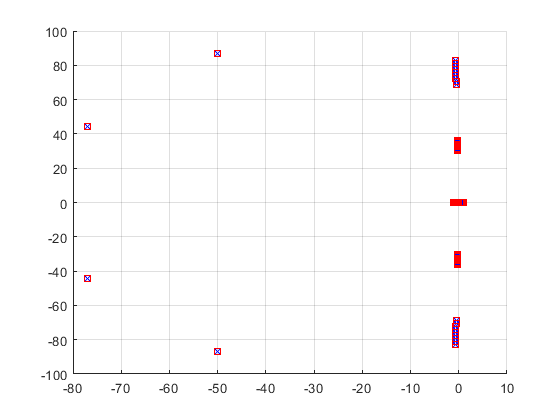


figure
Pol = pole(LV);
% xticks([-7,-6,-5,-4,-3,-2,-1,0,1]);
% xticklabels({'-7', '-6', '-5','-4','-3','-2','-1','0','1'})
hold on
Pcl = pole(CL);grid
plot(real(Pol),imag(Pol),'bx')
plot(real(Pcl),imag(Pcl),'rs')
hold off


CL = load("CL.mat").CL

PSS with 13 States, 11 Outputs, 10 Inputs, Continuous System.            
The PSS consists of the following blocks:                                
  v_x: Gridded real, 9 points in [95.9,1.77e+03], rate bounds [5.4,36.4].


get_ptraj_for_sim;


% [Y,T,X,U,TRAJ] = lpvinitial(CL,ptraj,x0,time_res)
[Y,T,X,U,TRAJ] = lpvlsim(CL,ptraj,u_in,time_res,x0)

Error using pss/lpvlsim>LOCALpgrid2simgrid (line 377)
ptraj must contain a field for each of the IVs in Dom

Error in pss/lpvlsim (line 139)
    [Values,Names,newtime,newu] = LOCALpgrid2simgrid(ptraj,P.Domain,uIn,tIn);   

% tile_lay_outputs = tiledlayout(length(CL.Data.OutputName),1)
% tile_lay_outputs.TileSpacing = 'compact';
% for i = 1:length(CL.Data.OutputName)
%     nexttile
%     plot(T,Y(:,i),'LineWidth',1);grid
%     subtitle(CL.Data.OutputName(i),'FontSize',12)
% %     subtitle(CL.Data.OutputName(i))
%     hold on
% end
% 
% tile_lay_inputs = tiledlayout(length(CL.Data.InputName),1)
% tile_lay_inputs.TileSpacing = 'compact';
% for i = 1:length(CL.Data.InputName)
%     nexttile
%     plot(T,U(:,i),'LineWidth',1);grid
%     subtitle(CL.Data.InputName(i))
%     hold on
% end
% 
% tile_lay_outputs = tiledlayout('flow');
% for i = 1:length(CL.Data.StateName)
%     nexttile
%     plot(T,X(:,i),'LineWidth',1);grid
%     subtitle(CL.Data.StateName(i))
%     hold on
% end



% Plot velocity/acceleration
% figure
% yyaxis left
% plot(time_res,v,'Linewidth',2);grid
% ax = gca;
% ax.FontSize = 10.2
% xlabel('Time [s]','FontSize', 16)
% ylabel('Velocity [m/s]','FontSize', 16)
% 
% % f = polyfit(t,v_x(:),3);
% % f_diff = polyder(f);
% % acc = polyval(f_diff,t);
% yyaxis right
% plot(time_res,acc,'Linewidth',2)
% ylabel('Accelceration [m/s^2]','FontSize', 16)
% legend('Velocity','Acceleration','Location','best')